clc; clear; close all

# Load 1D-FC Data

f = @(x, y) 4 + (1 + x.^2 + y.^2).*(sin(2.5*pi*x - 0.5) + cos(2*pi*y - 0.5))

f = function_handle with value:
    @(x,y)4+(1+x.^2+y.^2).*(sin(2.5*pi*x-0.5)+cos(2*pi*y-0.5))


l_theta = @(theta) [2*sin(theta/2), -sin(theta)];

C = 27;
d = 5;

load(['FC_data/A_d',num2str(d),'_C', num2str(27), '.mat']);
load(['FC_data/Q_d',num2str(d),'_C', num2str(27), '.mat']);
A = double(A);
Q = double(Q);

# Constructing Boundary Patch

## C2 Patch

Needs l(theta) data, the corners on the boundary in terms of theta, and function values on mesh

C2_patch = construct_C2_patch(f, 0.4, 2*pi-0.4, 0, 20, 20); % data associated with patch

C2_patch =   C2_patch_obj with properties:

          M_p: @(xi,eta)l_theta(l_A(xi))+l_theta(l_B(eta))-l_theta(theta_C)
            J: @(v)[theta_A*cos(v(1)*theta_A/2),(theta_B-2*pi)*cos((v(2)*(theta_B-2*pi)+2*pi)/2);-theta_A*cos(v(1)*theta_A),-(theta_B-2*pi)*cos(v(2)*(theta_B-2*pi)+2*pi)]
         n_xi: 20
        n_eta: 20
     xi_start: 0
       xi_end: 1
    eta_start: 0
      eta_end: 1
         f_XY: [21×21 double]
        x_min: 2.4493e-16
        x_max: 0.7947
        y_min: -0.3894
        y_max: 0.3894



[X, Y] = C2_patch.xy_mesh();
figure;
scatter(X(:), Y(:));
hold on;

## S Patch

window_patch_xi = construct_S_patch(f, 0.2, 0.6, 0.027, 20, 10)

window_patch_xi =   S_patch_obj with properties:

    M_p_general: @(xi,eta,H)l_theta(l_A(xi))+eta.*H.*nu(xi)
      J_general: @(v,H)[theta_diff*cos(l_A(v(1))/2)-v(2)*H*theta_diff*sin(l_A(v(1))),H*cos(l_A(v(1)));-1*theta_diff*cos(l_A(v(1)))-v(2)*H*theta_diff/2*sin(l_A(v(1))/2),H*cos(l_A(v(1))/2)]
              h: 0.0270
            M_p: @(xi,eta)M_p_general(xi,eta,H)
              J: @(v)J_general(v,H)
           n_xi: 20
          n_eta: 10
       xi_start: 0
         xi_end: 1
      eta_start: 0
        eta_end: 1
           f_XY: [11×21 double]
          x_min: 0.1997
          x_max: 0.7676
          y_min: -0.5646
          y_max: -0.0063


window_patch_eta = construct_S_patch(f, 2*pi-0.2, 2*pi-0.6, 0.027, 20, 10)

window_patch_eta =   S_patch_obj with properties:

    M_p_general: @(xi,eta,H)l_theta(l_A(xi))+eta.*H.*nu(xi)
      J_general: @(v,H)[theta_diff*cos(l_A(v(1))/2)-v(2)*H*theta_diff*sin(l_A(v(1))),H*cos(l_A(v(1)));-1*theta_diff*cos(l_A(v(1)))-v(2)*H*theta_diff/2*sin(l_A(v(1))/2),H*cos(l_A(v(1))/2)]
              h: 0.0270
            M_p: @(xi,eta)M_p_general(xi,eta,H)
              J: @(v)J_general(v,H)
           n_xi: 20
          n_eta: 10
       xi_start: 0
         xi_end: 1
      eta_start: 0
        eta_end: 1
           f_XY: [11×21 double]
          x_min: 0.1997
          x_max: 0.7676
          y_min: 0.0063
          y_max: 0.5646


S_patch = construct_S_patch(f, 0.6, 2*pi-0.6, 0.027, 255, 10)

S_patch =   S_patch_obj with properties:

    M_p_general: @(xi,eta,H)l_theta(l_A(xi))+eta.*H.*nu(xi)
      J_general: @(v,H)[theta_diff*cos(l_A(v(1))/2)-v(2)*H*theta_diff*sin(l_A(v(1))),H*cos(l_A(v(1)));-1*theta_diff*cos(l_A(v(1)))-v(2)*H*theta_diff/2*sin(l_A(v(1))/2),H*cos(l_A(v(1))/2)]
              h: 0.0270
            M_p: @(xi,eta)M_p_general(xi,eta,H)
              J: @(v)J_general(v,H)
           n_xi: 255
          n_eta: 10
       xi_start: 0
         xi_end: 1
      eta_start: 0
        eta_end: 1
           f_XY: [11×256 double]
          x_min: 0.5910
          x_max: 2.0000
          y_min: -1.0000
          y_max: 1.0000



[C2_norm, xi_norm, eta_norm] = C2_patch.compute_phi_normalization(window_patch_xi, window_patch_eta, 10);
eta_norm

eta_norm =     0.0970    0.0877    0.0823    0.0923    0.1140    0.1391    0.1636    0.1870    0.2115    0.2384    0.2636    0.2854    0.3041    0.3199    0.3332    0.3442    0.3529    0.3595    0.3642    0.3670    0.3679
    0.0968    0.0876    0.0822    0.0924    0.1140    0.1393    0.1638    0.1872    0.2116    0.2384    0.2636    0.2854    0.3041    0.3199    0.3332    0.3442    0.3529    0.3595    0.3642    0.3670    0.3679
    0.0962    0.0871    0.0818    0.0921    0.1139    0.1393    0.1640    0.1874    0.2117    0.2384    0.2636    0.2854    0.3041    0.3199    0.3332    0.3442    0.3529    0.3595    0.3642    0.3670    0.3679
    0.0952    0.0862    0.0811    0.0915    0.1135    0.1391    0.1640    0.1875    0.2118    0.2385    0.2636    0.2854    0.3041    0.3199    0.3332    0.3442    0.3529    0.3595    0.3642    0.3670    0.3679
    0.0936    0.0848    0.0799    0.0905    0.1128    0.1387    0.1638    0.1876    0.2119    0.2385    0.2636    0.2854    0.3041    0.3199    0

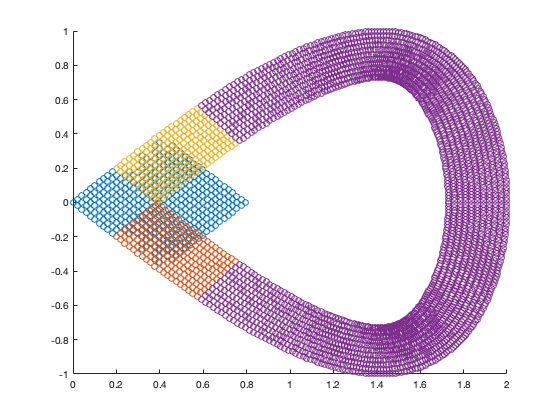

xy = C2_patch.M_p(xi_norm(1), xi_norm(2));
[X, Y] = window_patch_xi.xy_mesh();
scatter(X(:), Y(:))

[X, Y] = window_patch_eta.xy_mesh();
scatter(X(:), Y(:))

[X, Y] = S_patch.xy_mesh();
scatter(X(:), Y(:))

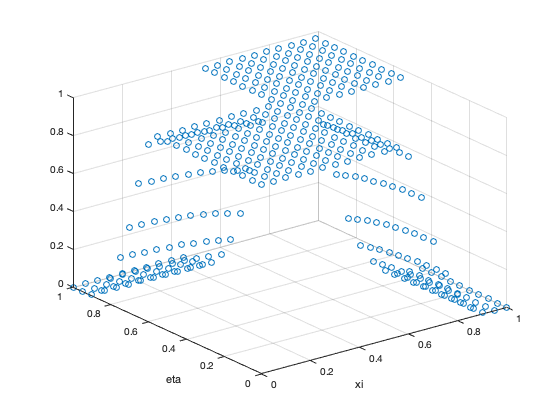

% [X, Y] = window_patch_eta.xy_mesh();
% scatter(X(:), Y(:))
%scatter(xi_norm(:), eta_norm(:))

[XI, ETA] = C2_patch.xi_eta_mesh();
C2_patch.phi(XI, ETA);
normalized_phi = C2_patch.phi(XI, ETA)./C2_norm;
%normalized_phi(isnan(normalized_phi)) = 1;
figure;
scatter3(XI(:), ETA(:), normalized_phi(:))
xlabel("xi")
ylabel("eta")


xi_norm

xi_norm =     0.0970    0.0877    0.0823    0.0923    0.1140    0.1391    0.1636    0.1870    0.2115    0.2384    0.2636    0.2854    0.3041    0.3199    0.3332    0.3442    0.3529    0.3595    0.3642    0.3670    0.3679
    0.0968    0.0876    0.0822    0.0924    0.1140    0.1393    0.1638    0.1872    0.2116    0.2384    0.2636    0.2854    0.3041    0.3199    0.3332    0.3442    0.3529    0.3595    0.3642    0.3670    0.3679
    0.0962    0.0871    0.0818    0.0921    0.1139    0.1393    0.1640    0.1874    0.2117    0.2384    0.2636    0.2854    0.3041    0.3199    0.3332    0.3442    0.3529    0.3595    0.3642    0.3670    0.3679
    0.0952    0.0862    0.0811    0.0915    0.1135    0.1391    0.1640    0.1875    0.2118    0.2385    0.2636    0.2854    0.3041    0.3199    0.3332    0.3442    0.3529    0.3595    0.3642    0.3670    0.3679
    0.0936    0.0848    0.0799    0.0905    0.1128    0.1387    0.1638    0.1876    0.2119    0.2385    0.2636    0.2854    0.3041    0.3199    0.

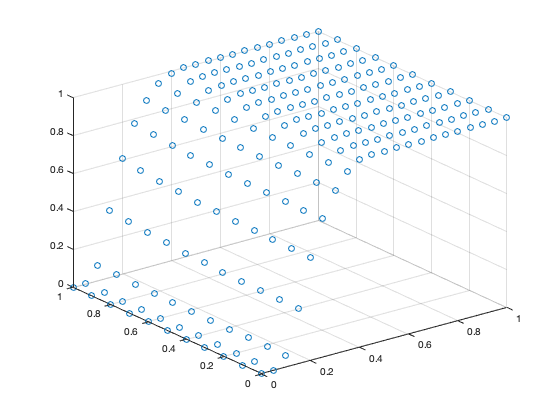

figure;
[XI, ETA] = window_patch_eta.xi_eta_mesh();
normalized_phi = window_patch_eta.window_phi(XI, ETA)./xi_norm;
figure;
scatter3(XI(:), ETA(:), normalized_phi(:))

# FC on C2 Patch and S Patch

Assumes we know what type the patches are, if not, we can simply add another entry that is enumeration of the patch types

% creates patch with data, including partition of unity
C2_fcont_patch = C2_patch.FC(C, d, A, Q, C2_norm)

C2_fcont_patch =   C2_patch_obj with properties:

          M_p: @(xi,eta)l_theta(l_A(xi))+l_theta(l_B(eta))-l_theta(theta_C)
            J: @(v)[theta_A*cos(v(1)*theta_A/2),(theta_B-2*pi)*cos((v(2)*(theta_B-2*pi)+2*pi)/2);-theta_A*cos(v(1)*theta_A),-(theta_B-2*pi)*cos(v(2)*(theta_B-2*pi)+2*pi)]
         n_xi: 47
        n_eta: 47
     xi_start: -1.3500
       xi_end: 1
    eta_start: -1.3500
      eta_end: 1
         f_XY: [48×48 double]
        x_min: -1.0669
        x_max: 0.7947
        y_min: -0.9036
        y_max: 0.9036


window_fcont_patch_xi = window_patch_xi.FC(C, d, A, Q, xi_norm)

window_fcont_patch_xi =   S_patch_obj with properties:

    M_p_general: @(xi,eta,H)l_theta(l_A(xi))+eta.*H.*nu(xi)
      J_general: @(v,H)[theta_diff*cos(l_A(v(1))/2)-v(2)*H*theta_diff*sin(l_A(v(1))),H*cos(l_A(v(1)));-1*theta_diff*cos(l_A(v(1)))-v(2)*H*theta_diff/2*sin(l_A(v(1))/2),H*cos(l_A(v(1))/2)]
              h: 0.0270
            M_p: @(xi,eta)M_p_general(xi,eta,H)
              J: @(v)J_general(v,H)
           n_xi: 20
          n_eta: 37
       xi_start: 0
         xi_end: 1
      eta_start: -2.7000
        eta_end: 1
           f_XY: [38×21 double]
          x_min: -0.3119
          x_max: 0.7676
          y_min: -1.1163
          y_max: -0.0063


window_fcont_patch_eta = window_patch_eta.FC(C, d, A, Q, eta_norm)

window_fcont_patch_eta =   S_patch_obj with properties:

    M_p_general: @(xi,eta,H)l_theta(l_A(xi))+eta.*H.*nu(xi)
      J_general: @(v,H)[theta_diff*cos(l_A(v(1))/2)-v(2)*H*theta_diff*sin(l_A(v(1))),H*cos(l_A(v(1)));-1*theta_diff*cos(l_A(v(1)))-v(2)*H*theta_diff/2*sin(l_A(v(1))/2),H*cos(l_A(v(1))/2)]
              h: 0.0270
            M_p: @(xi,eta)M_p_general(xi,eta,H)
              J: @(v)J_general(v,H)
           n_xi: 20
          n_eta: 37
       xi_start: 0
         xi_end: 1
      eta_start: -2.7000
        eta_end: 1
           f_XY: [38×21 double]
          x_min: -0.3119
          x_max: 0.7676
          y_min: 0.0063
          y_max: 1.1163


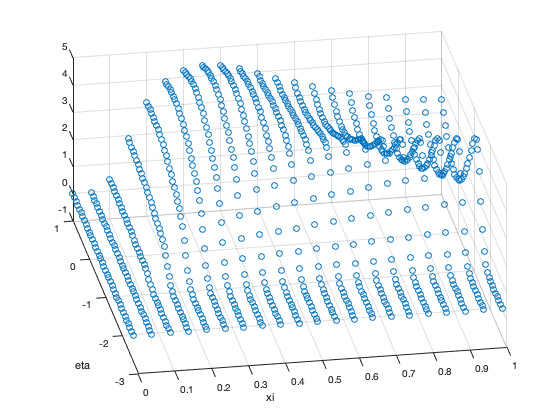

S_fcont_patch = S_patch.FC(C, d, A, Q, nan);

[XI, ETA] = window_fcont_patch_xi.xi_eta_mesh();
figure;
scatter3(XI(:), ETA(:), window_fcont_patch_eta.f_XY(:))
xlabel("xi")
ylabel("eta")


[f_XY, ~, in_range] = S_fcont_patch.locally_compute(1.23307, 1.17104, d)

f_XY = 8.0254

in_range = logical
   1


# Interpolation onto R

Note that we don't have any interior patches, so if any points aren't in the C2 or S patch, we just assume we know the value.

R_x_bounds = [C2_fcont_patch.x_min, S_fcont_patch.x_max];
R_y_bounds = [S_fcont_patch.y_min, S_fcont_patch.y_max];

h_R = 0.1;

[R_X, R_Y] = meshgrid(R_x_bounds(1):h_R:R_x_bounds(2), R_y_bounds(1):h_R:R_y_bounds(2));
f_R = zeros(size(R_X))

f_R =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0


theta_mesh = transpose(linspace(0, 2*pi, 100));
boundary_XY = l_theta(theta_mesh);
interior_polygon = inpolygon(R_X, R_Y, boundary_XY(:, 1), boundary_XY(:, 2))

interior_polygon = 35×38 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   


for i = 1:size(R_X, 1)
    for j = 1:size(R_X, 2)
        x = R_X(i, j);
        y = R_Y(i, j);
        
        if interior_polygon(i, j)
            f_R(i, j) = f(x, y);
        else
            [f_S, ~, in_range_S] = S_fcont_patch.locally_compute(x, y, d);            
            if in_range_S
                f_R(i, j) = f_S;
            else
                [f_C2, ~, in_range_C2] = C2_fcont_patch.locally_compute(x, y, d);
                [f_window_xi, ~, in_range_xi] = window_fcont_patch_xi.locally_compute(x, y, d);
                [f_window_eta, ~, in_range_eta] = window_fcont_patch_eta.locally_compute(x, y, d);
                
                if in_range_C2
                    f_R(i, j) = f_R(i, j) + f_C2;
                end
                if in_range_xi
                    f_R(i, j) = f_R(i, j) + f_window_xi;
                end
                if in_range_eta
                    f_R(i, j) = f_R(i, j) + f_window_eta;
                end
            end     
        end
    end
end

f_R

f_R =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0001  

[XI, ETA] = S_patch.xi_eta_mesh();
phi_S = S_patch.phi(XI, ETA)

phi_S =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0003    0.0006    0.0013    0.0023    0.0038    0.0057    0.0081    0.0109    0.0142    0.0180    0.0221    0.0266    0.0315    0.0366    0.0419    0.0475    0.0533    0.0592    0.0652    0.0713    0.0775    0.0837    0.0900    0.0962    0.1025    0.1087    0.1149    0.1211    0.1272    0.1333    0.1393    0.1452    0.1510    0.1568    0.1625    0.1681    0.1736    0.1790    0.1844    0.1896    0.1947    0.1998
         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0003    0.0006    0.0013    0.0023    0.0038    0.0057    0.0081    0.0109    0.0142    0.0180    0.0221    0.0266    0.0315    0.0366    0.0419    0.0475    0.0533    0.0592    0.0652    0.0713    0.0775    0.0837    0.0900    0.0962    0.1025    0.1087    0.1149    0.1211    0.1272    0.1333    0.1393    0.1452    0.1510    0.1568    0.1625    0.1681    0.1736    0.1790    0.1844    0.1896    0.1947 


f_R_XY = f(R_X, R_Y)

f_R_XY =     3.1846    0.9876    1.6509    4.5567    7.8936    9.7368    9.1101    6.4639    3.3543    1.5425    2.0211    4.4853    7.5185    9.3813    8.9801    6.4956    3.3205    1.3144    1.7570    4.5695    8.2675   10.7294   10.4047    7.2919    3.0831    0.3033    0.8587    4.8095   10.1404   13.7808   13.3840    8.8531    2.6421   -1.4909   -0.6738    5.2051   13.1373   18.5357
    0.2808   -1.6387   -0.9013    1.8981    5.0695    6.8368    6.3130    3.9255    1.1090   -0.5240   -0.0700    2.1890    4.9580    6.6462    6.2490    3.9244    0.9437   -0.9822   -0.6630    1.8457    5.1806    7.3691    6.9498    3.8982   -0.2150   -3.0135   -2.6801    0.8680    5.7372    9.0055    8.4152    3.8468   -2.3672   -6.6177   -6.1215   -0.7439    6.6278   11.5554
   -1.7961   -3.4670   -2.6712    0.0180    3.0249    4.7133    4.2798    2.1304   -0.4143   -1.8818   -1.4524    0.6135    3.1350    4.6612    4.2714    2.1019   -0.6900   -2.5335   -2.3218   -0.0893    2.9151    4.8586    4.363

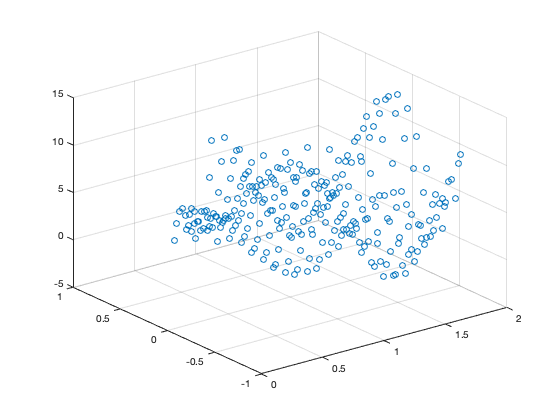

figure;
scatter3(R_X(interior_polygon), R_Y(interior_polygon), f_R_XY(interior_polygon))

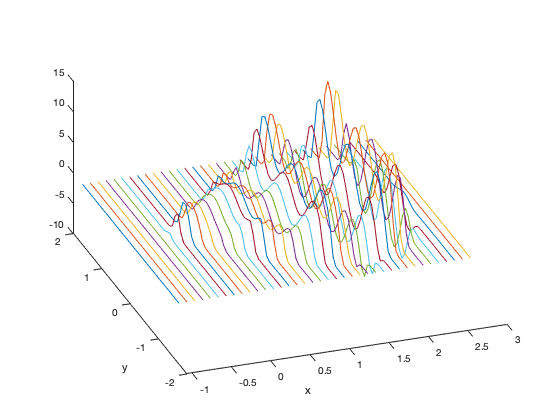

figure;
plot3(R_X, R_Y, f_R)
xlabel("x")
ylabel('y')

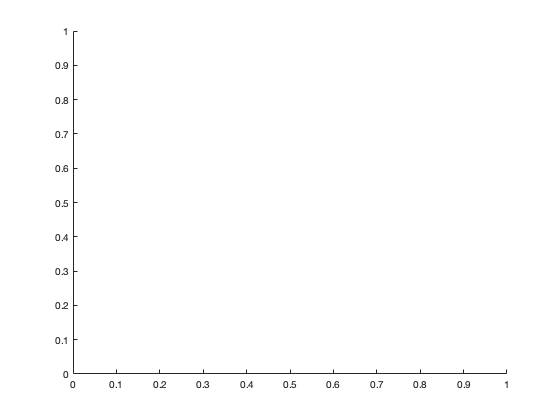


figure;
scatter(R_X(isnan(f_R)), R_Y(isnan(f_R)))

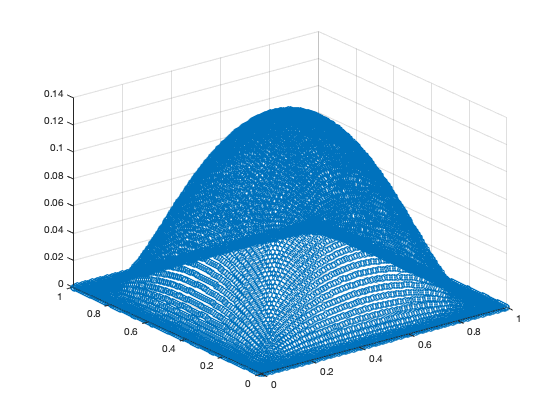

phi_xy = @(x, y) exp(-1./(1-(2*x-1).^2)).*exp(-1./(1-(2*y-1).^2));
[X, Y] = meshgrid(linspace(0, 1, 100));
figure;
scatter3(X(:), Y(:), phi_xy(X(:), Y(:)))

# Construction of Patches

Note that these are domain specific functions

function C2_patch = construct_C2_patch(f, theta_A, theta_B, theta_C, n_xi, n_eta)
    l_theta = @(theta) [2*sin(theta/2), -sin(theta)];
    
    l_A = @(xi) xi*(theta_A - theta_C) + theta_C;
    l_B = @(eta) eta*(theta_B - theta_C - 2*pi) + theta_C + 2*pi; % account for wrap around
    
    M_p = @(xi, eta) l_theta(l_A(xi)) + l_theta(l_B(eta)) - l_theta(theta_C);
    J = @(v) [theta_A*cos(v(1)*theta_A/2) (theta_B-2*pi)*cos((v(2)*(theta_B-2*pi)+2*pi)/2); -theta_A*cos(v(1)*theta_A) -(theta_B-2*pi)*cos(v(2)*(theta_B-2*pi)+2*pi)];
    
    xi_mesh = linspace(0, 1, n_xi+1);
    eta_mesh = linspace(0, 1, n_eta+1);
    
    [XI, ETA] = meshgrid(xi_mesh, eta_mesh);
    XY = M_p(XI(:), ETA(:));
    
    f_XY = reshape(f(XY(:, 1), XY(:, 2)), [n_eta+1, n_xi+1]);
    
    C2_patch = C2_patch_obj(M_p, J, n_xi, n_eta, 0, 1, 0, 1, f_XY) % data associated with patch
end

function S_patch = construct_S_patch(f, theta_A, theta_B, h, n_xi, n_eta)
    l_theta = @(theta) [2*sin(theta/2), -sin(theta)];
    
    l_A = @(xi) (theta_B - theta_A)*xi + theta_A;
    nu = @(xi) [cos(l_A(xi)), cos(l_A(xi)/2)] ./ sqrt(cos(l_A(xi)).^2 + cos(l_A(xi)/2).^2);
    
    M_p_general = @(xi, eta, H) l_theta(l_A(xi)) + eta.*H.*nu(xi);
    % H is a function of h and n_eta
    
    theta_diff = theta_B - theta_A;
    J = @(v, H) [theta_diff*cos(l_A(v(1))/2)-v(2)*H*theta_diff*sin(l_A(v(1))), H*cos(l_A(v(1))); -1*theta_diff*cos(l_A(v(1)))-v(2)*H*theta_diff/2*sin(l_A(v(1))/2), H*cos(l_A(v(1))/2)];
    
    xi_mesh = linspace(0, 1, n_xi+1);
    eta_mesh = linspace(0, 1, n_eta+1);
    
    [XI, ETA] = meshgrid(xi_mesh, eta_mesh);
    XY = M_p_general(XI(:), ETA(:), h*n_eta);
    
    f_XY = reshape(f(XY(:, 1), XY(:, 2)), [n_eta+1, n_xi+1]);
    
    S_patch = S_patch_obj(M_p_general, J, n_xi, n_eta, 0, 1, 0, 1, f_XY, h);
end

% function f_y = f(x, y)
%     r = sqrt(x.^2 + y.^2);
%     f_y = zeros(size(x));
%     f_y(r < 0.56) = exp(1./(1/0.56*r(r < 0.56).^2-0.56));
%     f_y(r >= 0.56) = 0;
% end